## IED-TW Delay VS NA-LC Delay

clc; clear; addpath z_toolbox; addpath E:\IEDpropagation\z_toolbox\Violinplot;
% Load IED traveling wave data
load(fullfile('step3_IEDtravelingWave', 'IEDtw_meth-None_TD-6d0.mat'));
% Load NA cross-correlation data
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_xcorr100ms_Rmax_delay_allSubject.mat'));
nS = 13; subID = 'sub-0014';
%% Extract IED transfer matrix
% Extract traveling wave delay matrix and transfer rate matrix
IEDtwD = IEDtw(nS).indirectTransferDelayMatrix;
IEDtwRate = IEDtw(nS).indirectTransferRateMatrix;
% Extract cross-correlation delay and correlation coefficient matrices
NAxcD = Delay_allSubject{nS};
NAxcR = xcR_allSubject{nS};
Mask = IEDtwRate;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(NAxcR) | isinf(NAxcR) | NAxcR <= zThd) = 0;
Mask(isnan(NAxcD) | isinf(NAxcD)) = 0;
% Extract valid data points using the mask
IEDtwD = IEDtwD(Mask>0);
NAxcD = NAxcD(Mask>0);
x = IEDtwD; y = NAxcD;
[r, p] = corr(x, y, "type", "Spearman");
disp(r); disp(p);

    0.3849

  4.3477e-200



figure('Units', 'centimeters', 'Position', [5, 5, 39, 33]);
subplot(3, 4, 1);
f_densityScatter(x, y, 4);
hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); 
hold off;
xlim([min(x), max(x)]);
ylim([min(y), max(y)]);
xlabel('IED-TW Delay (ms)'); 
ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear; 
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED.mat'), ...
    'R_twxcD_res', 'R_twxcD', 'P_twxcD_res', 'P_twxcD');
disp(mean(R_twxcD)); disp(std(R_twxcD)); 

    0.3403

    0.1155



disp(mean(R_twxcD_res(:, 6))); disp(std(R_twxcD_res(:, 6)));

    0.2460

    0.1041



P_twxcD = P_twxcD*length(P_twxcD); 
if max(P_twxcD)<0.05; disp('sigificant'); end

sigificant


P_twxcD_res = P_twxcD_res(:, 6)*size(P_twxcD_res, 1);
if max(P_twxcD_res)<0.05; disp('sigificant'); end

sigificant


for nS = 1:length(R_twxcD)
    Rstr{nS} = 'Raw'; 
    Rstr{47+nS} = 'Partial';
end
R(1:47) = R_twxcD; R(48:47*2) = R_twxcD_res(:, 6);
subplot(3, 4, 2);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Raw', 'Partial'}, ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [1, 0.6, 0.2; 0.8, 0.3, 0.05], ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]); ylim([0, 0.7]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## IED-LC Delay VS NA-LC Delay

clc; clear;
% Load IED and NA cross-correlation data
load(fullfile('step6_NAxcorr_polyfit',  'NAnon6d0IED_xcorr100ms_Rmax_delay_allSubject.mat'));
NAdelay = Delay_allSubject;
NAr = xcR_allSubject;
load(fullfile('step5_IEDxcorr_polyfit', 'IED6d0_xcorr100ms_Rmax_delay_allSubject.mat'));
IEDdelay = Delay_allSubject;
IEDr = xcR_allSubject;
nS = 13; subID = 'sub-0014';
%% Extract transfer matrix
% Extract IED cross-correlation delay and correlation coefficient matrices
IEDxcD = IEDdelay{nS};
IEDxcR = IEDr{nS};
% Extract NA cross-correlation delay and correlation coefficient matrices
NAxcD = NAdelay{nS};
NAxcR = NAr{nS};
% Extract valid data points using the mask
Mask = IEDxcR;
Mask = Mask - diag(diag(Mask));
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(NAxcR) | isinf(NAxcR) | NAxcR <= zThd) = 0;
Mask(isnan(NAxcD) | isinf(NAxcD)) = 0;
Mask(isnan(IEDxcR) | isinf(IEDxcR) | IEDxcR <= zThd) = 0;
Mask(isnan(IEDxcD) | isinf(IEDxcD)) = 0;
IEDxcD = IEDxcD(Mask>0);
NAxcD = NAxcD(Mask>0);
x = IEDxcD; y = NAxcD;
[r, p] = corr(x, y, 'type', 'Spearman');
disp(r); disp(p);

    0.5841

     0



subplot(3, 4, 3);
f_densityScatter(x, y, 4); hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('IED-LC Delay (ms)'); ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_IEDxcD_polyfit_delays.mat'), ...
    'RxcD', 'RxcD_rED', 'PxcD', 'PxcD_rED');
disp(mean(RxcD)); disp(std(RxcD));

    0.4923

    0.1420



disp(mean(RxcD_rED)); disp(std(RxcD_rED));

    0.4183

    0.1355



PxcD = PxcD*length(PxcD);
PxcD_rED = PxcD_rED*length(PxcD_rED);
if max(PxcD)<0.05; disp('sigificant'); end

sigificant


if max(PxcD_rED)<0.05; disp('sigificant'); end

sigificant


for nS = 1:length(RxcD)
    Rstr{nS} = 'Raw';
    Rstr{47+nS} = 'Partial';
end
R(1:47) = RxcD; R(48:47*2) = RxcD_rED;
subplot(3, 4, 4);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Raw', 'Partial'}, ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [1, 0.6, 0.2; 0.8, 0.3, 0.05], ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]); ylim([0, 0.9]);
set(gca, 'box', 'off',  'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## Euclidean Distance VS NA-LC Delay

clc; clear;
% Load IED traveling wave data
load(fullfile('step3_IEDtravelingWave', 'IEDtw_meth-None_TD-6d0.mat'));
% Load IED cross-correlation data
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_xcorr100ms_Rmax_delay_allSubject.mat'));
% Process each subject individually
nS = 13; subID = 'sub-0014';
% Load Euclidean distance matrix
load(fullfile('step2_channelDistance', [subID, '_EuclideabDistanceMatrix.mat']));
%% Extract IED transfer matrix
% Extract traveling wave delay matrix and transfer rate matrix
IEDtwRate = IEDtw(nS).indirectTransferRateMatrix;
% Extract cross-correlation delay and correlation coefficient matrices
NAxcD = Delay_allSubject{nS};
NAxcR = xcR_allSubject{nS};
Mask = IEDtwRate;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(NAxcR) | isinf(NAxcR) | NAxcR <= zThd) = 0;
Mask(isnan(NAxcD) | isinf(NAxcD)) = 0;
% Extract valid data points using the mask
ED = DistanceWorld(Mask>0);
NAxcD = NAxcD(Mask>0);
[polyModel, Curve, Ftest] = f_polyfit(ED, NAxcD, 6);
disp(polyModel.adjR2); disp(Ftest.Fstat); disp(Ftest.p_value);

    0.6309

   1.6200e+03

     0



subplot(3, 3, 4);
f_densityScatter(ED, NAxcD, 5); hold on;
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(ED), max(ED)]); ylim([min(NAxcD), max(NAxcD)]);
xlabel('Euclidean Distance (mm)'); ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step6_NAxcorr_polyfit', ...
    'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED.mat'), ...
    'adjR2_xcDED', 'p_adjR2_xcDED');
x = adjR2_xcDED(:, 6);
p = p_adjR2_xcDED(:, 6)*size(p_adjR2_xcDED, 1);
disp(mean(x)); disp(std(x));

    0.6488

    0.0962



if max(p)<0.05; disp('significant'); end

significant


for nS = 1:length(x)
    adjR2str{nS} = 'ED vs. NA-LC Delay';
end
subplot(3, 3, 7);
vs = violinplot(x, adjR2str, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [0.9, 0.1, 0.1; 0.4, 0, 0], ...
    'MarkerSize', 16);
ylabel('Adjusted R^2');
xlim([0.5, 1.5]); ylim([0.3, 0.9]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## NA Lag FC VS NA-LC Delay

clc; clear; 
% Load IED traveling wave data
load(fullfile('step3_IEDtravelingWave', 'IEDtw_meth-None_TD-6d0.mat'));
% Load IED cross-correlation data
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_xcorr100ms_Rmax_delay_allSubject.mat'));
% Process each subject individually
nS = 13; subID = 'sub-0014';
%% Extract IED transfer matrix
% Extract traveling wave delay matrix and transfer rate matrix
IEDtwRate = IEDtw(nS).indirectTransferRateMatrix;
% Extract cross-correlation delay and correlation coefficient matrices
NAxcD = Delay_allSubject{nS};
NAxcR = xcR_allSubject{nS};
Mask = IEDtwRate;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
Mask(Mask<0.1) = 0;
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(NAxcR) | isinf(NAxcR) | NAxcR <= zThd) = 0;
Mask(isnan(NAxcD) | isinf(NAxcD)) = 0;
% Extract valid data points using the mask
NAxcD = NAxcD(Mask>0);
NAxcR = log(NAxcR(Mask>0));
x = NAxcR; y = NAxcD;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.3953

  6.5508e-212



subplot(3, 3, 5);
f_densityScatter(x, y, 5); hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('log(NA Lag FC)'); ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_XC100ms_polyfit_delays_Rmas_ED.mat'), ...
    'R_xcDR', 'R_xcDR_res', 'P_xcDR', 'P_xcDR_res');
x = R_xcDR; y = R_xcDR_res(:, 6);
P_xcDR = P_xcDR*length(P_xcDR);
P_xcDR_rED = P_xcDR_res(:, 6)*size(P_xcDR_res, 1);
disp(mean(x)); disp(std(x)); disp(mean(y)); disp(std(y));

   -0.4281

    0.1389

   -0.4256

    0.1441



if max(P_xcDR)<0.05; disp('sigificant'); end

sigificant


if max(P_xcDR_rED)<0.05; disp('sigificant'); end

sigificant


for nS = 1:length(x)
    Rstr{nS} = 'Raw';
    Rstr{47+nS} = 'Partial';
end
R(1:47) = x; R(48:47*2) = y;
subplot(3, 3, 8);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Raw', 'Partial'}, ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [0.9, 0.1, 0.1; 0.4, 0, 0], ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]); ylim([-0.8, 0]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);

## SC Strength VS NA-LC Delay

clc; clear; 
% Load fiber count data for all subjects
load(fullfile('step2_fiberTrack',  'FiberMatrix_ncount_length_qa_allsubject.mat'), 'fiberCount', 'fiberLength');
% Load cross-correlation data
load(fullfile('step6_NAxcorr_polyfit',  'NAnon6d0IED_xcorr100ms_Rmax_delay_allSubject.mat'));
% Process each subject individually
nS = 13; subID = 'sub-0014';
% Load Euclidean distance matrix
load(fullfile('step2_channelDistance', [subID, '_EuclideabDistanceMatrix.mat']));
% Extract cross-correlation delay and correlation coefficient matrices
NAxcD = Delay_allSubject{nS};
NAxcR = xcR_allSubject{nS};
fibN = fiberCount{nS};
Mask = NAxcR;
Mask = Mask - diag(diag(Mask));
Mask(isnan(Mask)) = 0;
zThd = 0.5 * log((1 + 0.3) ./ (1 - 0.3));
Mask(isnan(NAxcR) | isinf(NAxcR) | NAxcR <= zThd) = 0;
Mask(isnan(NAxcD) | isinf(NAxcD)) = 0;
Mask(fibN==0) = 0;
% Extract valid data
NAxcD = NAxcD(Mask>0);
fibN = fibN(Mask>0);
fibN = log(fibN);
x = fibN; y = NAxcD;
[r, p] = corr(x, y, 'Type', 'Spearman');
disp(r); disp(p);

   -0.4702

   1.9536e-46



subplot(3, 3, 6);
f_densityScatter(x, y, 5); hold on;
[~, Curve, ~] = f_polyfit(x, y, 1);
plot(Curve.x, Curve.y, 'r-', 'LineWidth', 2); hold off;
xlim([min(x), max(x)]); ylim([min(y), max(y)]);
xlabel('SC Strength'); ylabel('NA-LC Delay (ms)');
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clc; clear;
load(fullfile('step6_NAxcorr_polyfit', 'NAnon6d0IED_XC100ms_polyfit_delay_fibN.mat'), ...
    'R_fibNxcD', 'R_fibNxcD_rED', 'P_fibNxcD', 'P_fibNxcD_rED');
idx = find(R_fibNxcD~=0);
R_fibNxcD = R_fibNxcD(idx);
R_fibNxcD_rED = R_fibNxcD_rED(idx);
P_fibNxcD = P_fibNxcD(idx);
P_fibNxcD = P_fibNxcD*length(P_fibNxcD);
P_fibNxcD_rED = P_fibNxcD_rED(idx);
P_fibNxcD_rED = P_fibNxcD_rED*length(P_fibNxcD_rED);
x = R_fibNxcD; y = R_fibNxcD_rED;
disp(mean(x)); disp(std(x)); disp(mean(y)); disp(std(y));

   -0.4492

    0.0988

   -0.0813

    0.0914



if max(P_fibNxcD)<0.05; disp('sigificant'); end

sigificant


if max(P_fibNxcD_rED)<0.05
    disp('sigificant');
else
    disp(length(find(P_fibNxcD_rED>0.05)));
end

    22



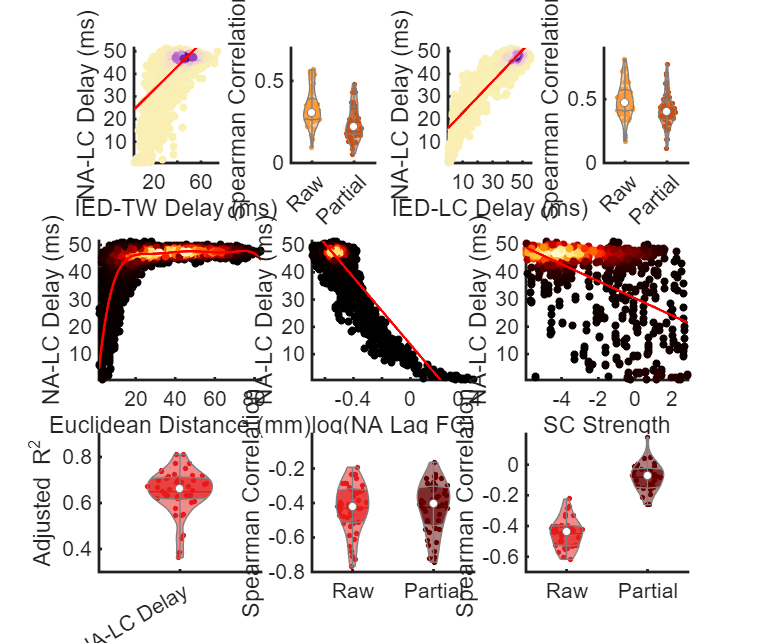

Rstr = {}; R = [];
for nS = 1:length(x)
    Rstr{nS} = 'Raw';
    Rstr{33+nS} = 'Partial';
end
R(1:33) = x; R(34:33*2) = y;
subplot(3, 3, 9);
vs = violinplot(R, Rstr, 'QuartileStyle','shadow', ...
    'Width', 0.2, 'GroupOrder', {'Raw', 'Partial'}, ...
    'ShowMean', true, 'ViolinAlpha', 0.5, ...
    'ViolinColor', [0.9, 0.1, 0.1; 0.4, 0, 0], ...
    'MarkerSize', 16);
ylabel('Spearman Correlation');
xlim([0.5, 2.5]); ylim([-0.7, 0.2]);
set(gca, 'box', 'off', 'FontName', 'Arial', 'FontSize', 16, 'LineWidth', 2);